# Exercise Session 1 - Input Output system (the first 3 exercises are the most important)

## Exercise 1 

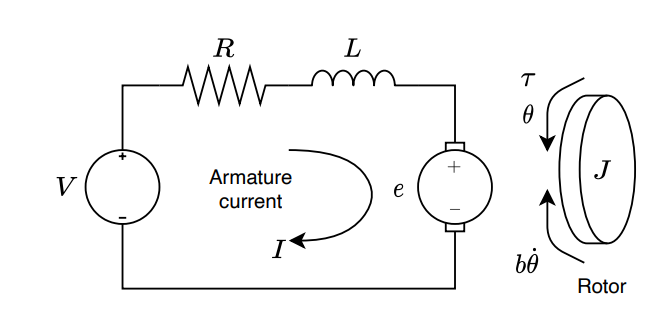

### 1. Derive a state space model of the DC-motor system, where voltage $V$ is considered as input and rotational velocity $\omega =\dot{\theta}$ is considered as output. 

Since a general state space model is on the form:


$$\dot{x} =\mathrm{Ax}+\mathrm{Bu}$$


State space variables are the variables that change inside the system, $V$ $I$ and $\omega$

Representing the input voltage as $V\;-\;K\;\omega =L\dot{I} +R\;I$

$b\;\dot{\theta}$ is the viscous friction 

Tourque constant $K_t$

To compute the measured tourque $\tau$ 


$$\tau =b\;\omega$$


Note: If the system is $\dot{x} =f\left(x,u,t\right)$, then if $x$ and $u$ are linear, then the system is linear. 

To model the system, we need to write up the electrical equation and an mechanical equation.

 The electrical equation is based on the circuit of the left side of the Figure. 

We use Kirchoffs Current Law, that states that the voltage drop across the entire system, must be 0. 

We start with the Voltage input:

The voltage drop across the battery in the direction of the amature current is: $-V$

The voltage drop across the resistor is: $R\cdot I$

The voltage drop across the inductive part is: $L\cdot \frac{\textrm{dI}}{\textrm{dt}}$ 

The voltage drop across the back emf is a little bit more tricky. Back emf is given as the motor torque constant times the rotational velocity:


$$e=K_e \dot{\theta} =K_e \omega$$


Combining these expressions into the electrical equation, using Kirchoffs law, gives:


$$-V+R\cdot I+L\cdot \frac{\mathrm{dI}}{\mathrm{dt}}+K_e \dot{\theta} =0$$


For the mechanical part, we have the moment of inertia $J$and torque $\tau =K_t I$and $\tau =b\omega +J\ddot{\theta}$


$$\tau =b\omega +J\ddot{\theta}$$


The state space equations are often dependent on time, and since I is dependent on time, and omega is dependent on time, we use these as the state space variables. **Note: **These are not sufficient conditions to determine wether a variable in the model should be a state space variable, but rather a rule of thumb. 

Let $x\left(t\right)=\left\lbrack \begin{array}{c}
\omega \left(t\right)\\
I\left(t\right)
\end{array}\right\rbrack$ . For notation purposes, i will disregard $\left(t\right)$

First we take the time derivative of the state space vector, which is given as


$$\dot{x} =\left\lbrack \begin{array}{c}
\ddot{\theta} \\
\dot{I} 
\end{array}\right\rbrack =\textrm{Ax}+\textrm{Bu}$$



$$=\left\lbrack \begin{array}{cc}
 & \\
 & 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{\theta} \\
I
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\\

\end{array}\right\rbrack V$$


Note that $u$ is the input to the system, which in this case is $V$

To fill out the matrices, we need to isolate the state space variables in the Electromechanical equations:


$$\ddot{\theta} =\frac{K_t I-b\dot{\theta} }{J}$$



$$\dot{I} =\frac{V-R\cdot I-k_e \omega }{L}$$


And the coefficients of $\dot{\theta}$ and $I$are put into the A matrix.


$$A=\left\lbrack \begin{array}{cc}
-\frac{b}{J} & \frac{K_t }{J}\\
-\frac{K_e }{L} & -\frac{R}{L}
\end{array}\right\rbrack$$



$$B=\left\lbrack \begin{array}{c}
0\\
\frac{1}{L}
\end{array}\right\rbrack$$


Thus 


$$\dot{x} =\left\lbrack \begin{array}{c}
\ddot{\theta} \\
\dot{I} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{b}{J} & \frac{K_t }{J}\\
-\frac{K_e }{L} & -\frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{\theta} \\
I
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{L}
\end{array}\right\rbrack V$$


Next we need to find the output 


$$y=\mathrm{Cx}+\mathrm{Du}$$


**Note: **$y=\omega$ is a scalar, so the dimensions of the $C\in {\mathbb{R}}^{1\times 2}$ and $D\in {\mathbb{R}}^{1\times 1}$ matrices are different


$$\omega ={\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
\omega \left(t\right)\\
I\left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack V$$


So now i have the state space model of the system:


$$\dot{x} =\left\lbrack \begin{array}{c}
\ddot{\theta} \\
\dot{I} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{b}{J} & \frac{K_t }{J}\\
-\frac{K_e }{L} & -\frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{\theta} \\
I
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{L}
\end{array}\right\rbrack V$$



$$\omega ={\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
\omega \left(t\right)\\
I\left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack V$$


### 2. Compute the eigenvalues of the system matrix. Where in the complex plane are these located and why? Use the following values:


$$\begin{array}{l}
J=0\ldotp 01\\
R=1\\
L=0\ldotp 5\\
b=0\ldotp 1\\
K_t =0\ldotp 01\\
K_e =0\ldotp 01
\end{array}$$


J = 0.01;
R = 1;
L = 0.5;
b = 0.1;
Kt = 0.01;
Ke = 0.01;

Lets write up the state space model:

A = [-b/J Kt/J; -Ke/L -R/L];
B = [0; 1/L];
C = [1 0];
D = 0;

Find the eigenvalues of the system matrix which is $A$

eA = eig(A)

eA =    -9.9975
   -2.0025


These eigenvalues are both negative, entailing that the system is stable. 

### 3. Implement the model in MATLAB and simulate a step response. 

To simulate the step response in matlab, we can use the state space representation method. This converts the continuous-time model to a state space model. 

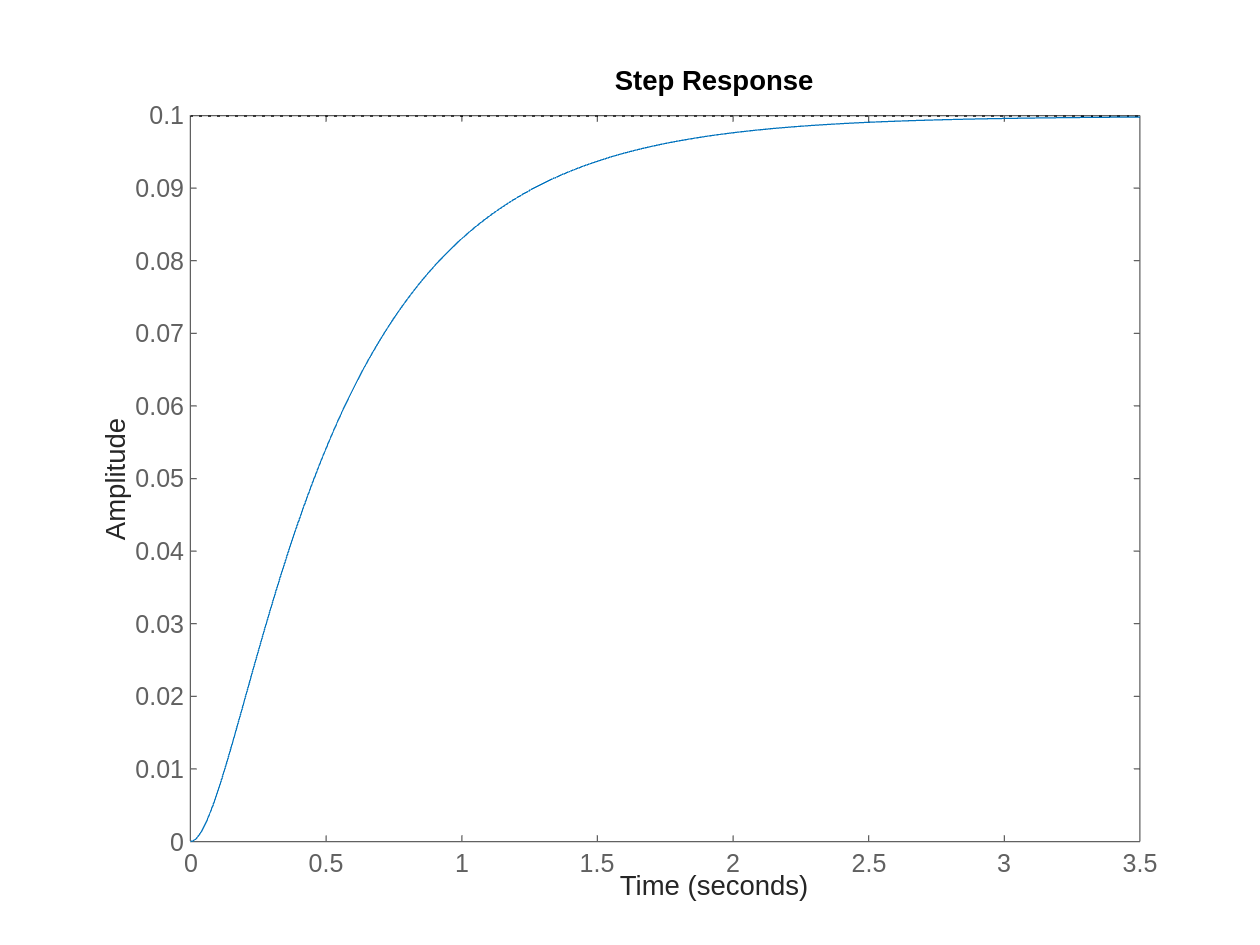

StateSpaceRepresentation = ss(A,B,C,D);
stepplot(StateSpaceRepresentation)

### 4. Change the model to also output the amature current, I, and simulate a step response. What does the response indicate. 

At the moment, the model only outputs the $\omega$, so in order to make it output the Amature current, i would let


$$y=\left\lbrack \begin{array}{c}
\omega \\
I
\end{array}\right\rbrack$$


Then i need to revaluate the coeficient matrices, $C$ and $D$


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\omega \\
I
\end{array}\right\rbrack =C\left\lbrack \begin{array}{c}
\omega \\
I
\end{array}\right\rbrack +\mathrm{DV}\\
=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega \\
I
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack V
\end{array}$$


By changing $C=I\in {\mathbb{R}}^{2\times 2}$ where $I$ is the Identity matrix, and $D$ to match the dimensions, we can now reevaluate the simulation:

C = [1 0; 0 1];
D = [0; 0];

Simulate:

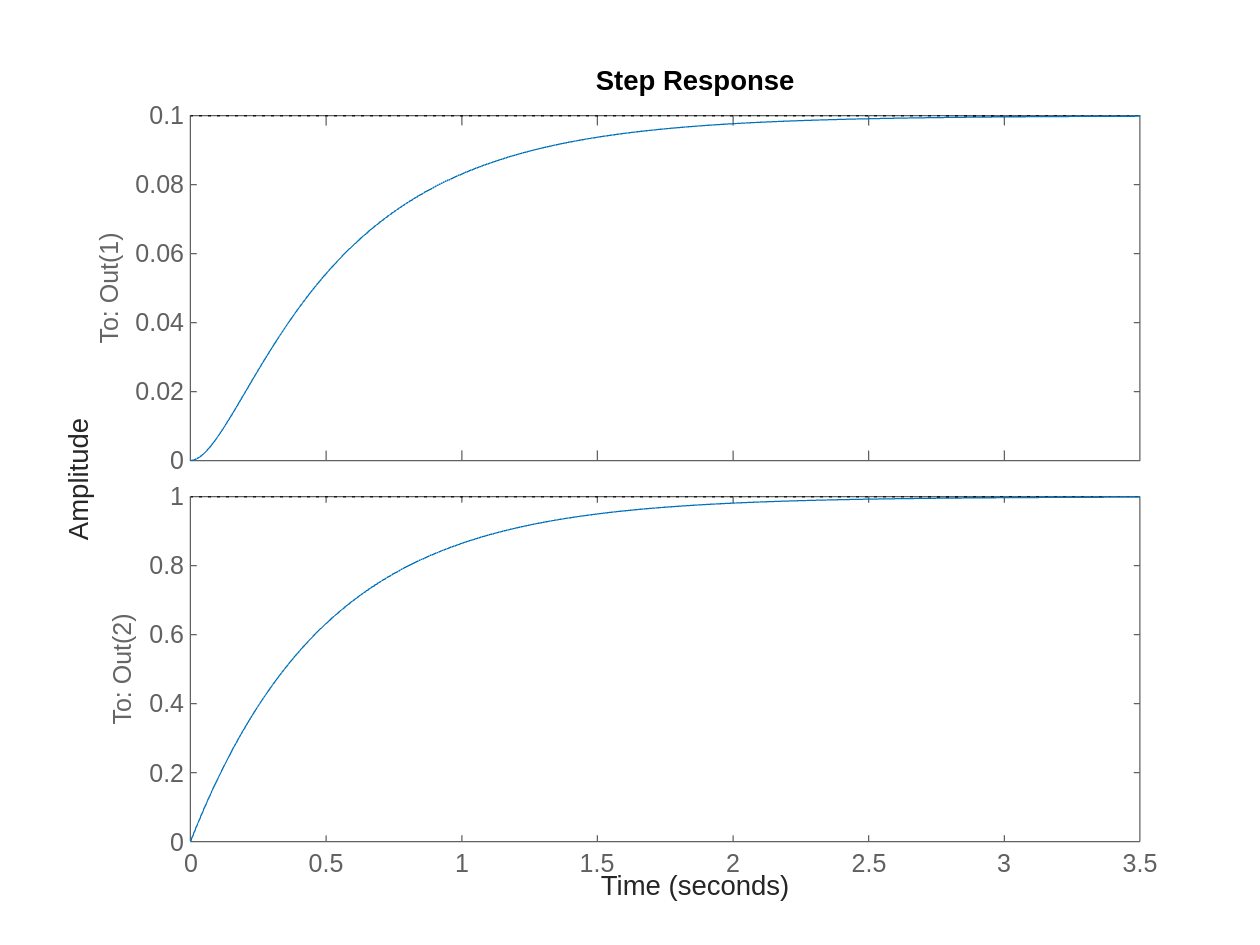

StateSpaceRepresentation = ss(A,B,C,D);
stepplot(StateSpaceRepresentation)

### 5. Simplify the model to only consider the mechanical dynamics. That is, assume $\dot{I} =0$

First i need to recompute the model. Lets start with the electrical equation:

First we take the electronic model, and let $\dot{I} =0$


$$-V+R\cdot I+L\cdot \dot{I} +K_e \dot{\theta} =0\Rightarrow -V+R\cdot I+K_e \omega =0\;$$


$\Downarrow$Isolate I


$$-V+R\cdot I+K_e \omega =0$$



$$\Downarrow$$



$$I=\frac{V-K_e \omega }{R}$$


Then i need to insert that into the mechanical equation. Recall that $\tau =K_t \cdot I$, and $\ddot{\theta} =\dot{\omega}$


$$\tau =b\omega +J\dot{\omega} =K_t \cdot I$$


Inserting 


$$K_t \cdot \frac{V-K_e \omega }{R}=b\omega +J\dot{\omega}$$


Then isolating $\dot{\omega}$


$$\frac{K_t \cdot \frac{V-K_e \omega }{R}-b\omega }{J}=\dot{\omega}$$



$$\Downarrow$$



$$\frac{\frac{K_t V}{R}-\frac{{K_t K}_e \omega }{R}-b\omega }{J}=\dot{\omega}$$



$$\Downarrow$$



$$\frac{K_t V}{R\cdot J}-\frac{{K_t K}_e \omega }{R\cdot J}-\frac{b\omega }{J}=\dot{\omega}$$



$$\Downarrow$$



$$V\frac{K_t }{R\cdot J}-\omega \left(\frac{{K_t K}_e }{R\cdot J}+\frac{b}{J}\right)=\dot{\omega}$$


Then i can reevaluate the model

if we let 

$\dot{\omega} =A\omega +\textrm{BV}$, then we have the correct form in a simplified version.


$$\dot{\omega} =\left(\frac{{K_t K}_e }{R\cdot J}-\frac{b}{J}\right)\omega +\frac{K_t }{R\cdot J}V$$


For the output $y=Cx+\textrm{Du}$:

Where $x=\left\lbrack \begin{array}{c}
\omega \\
I
\end{array}\right\rbrack$

and we want the same output:


$$y=\left\lbrack \begin{array}{c}
\omega \\
I
\end{array}\right\rbrack$$


Thus $C=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack =I$

### 6. Simulate the simplified system and compare the step response to the original systems response. Then try to increse the intertia to $J=0\ldotp 2$. What can you conclude from this experiment?

A = [((Kt*Ke)/(R*J)-b/J) 0; ((Kt*Ke)/(R*J)-b/J) 0]

A =    -9.9900         0
   -9.9900         0


B = [Kt/(R*J); 0]

B =      1
     0



C = [1 0; 0 1]

C =      1     0
     0     1


D = [0; 0]

D =      0
     0


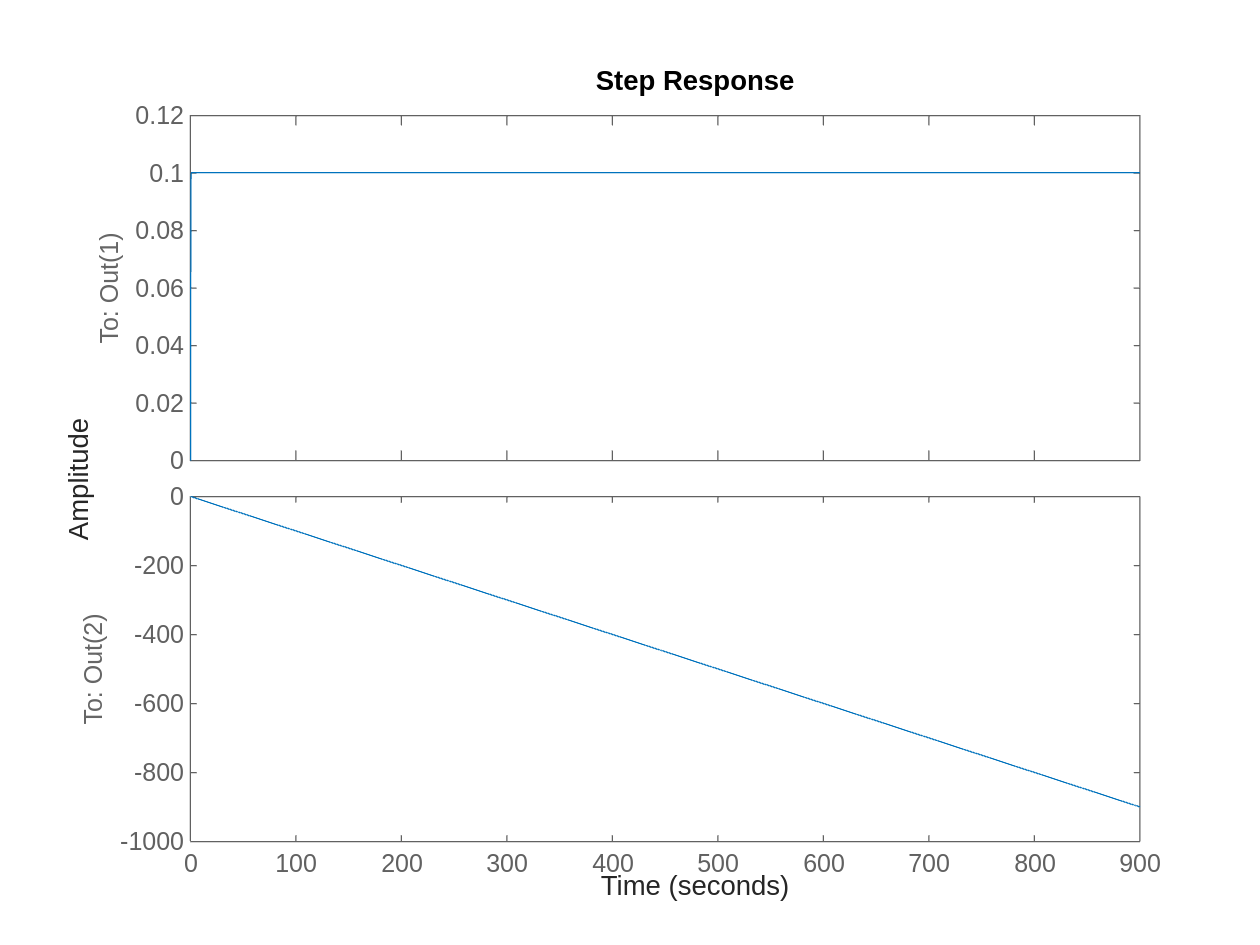

StateSpaceRepresentation = ss(A,B,C,D);
stepplot(StateSpaceRepresentation)

J=0.2;

StateSpaceRepresentation = ss(A,B,C,D);
stepplot(StateSpaceRepresentation)